clear all; close all;
Jm = 1.13e-2; b = 0.028; La = 0.1;
Ra = 0.45; Kt = 0.067; Ke = 0.067;


## plant TF

numG =Kt;
denG = conv([Jm,b],[La,Ra])+[0 0 Kt*Ke];
G = tf(numG,denG);

## PID control gains

Kp = 3*[1 1 1];
Ki = 15*[0 1 1];
Kd = 0.3*[0 0 1];


## Simulations

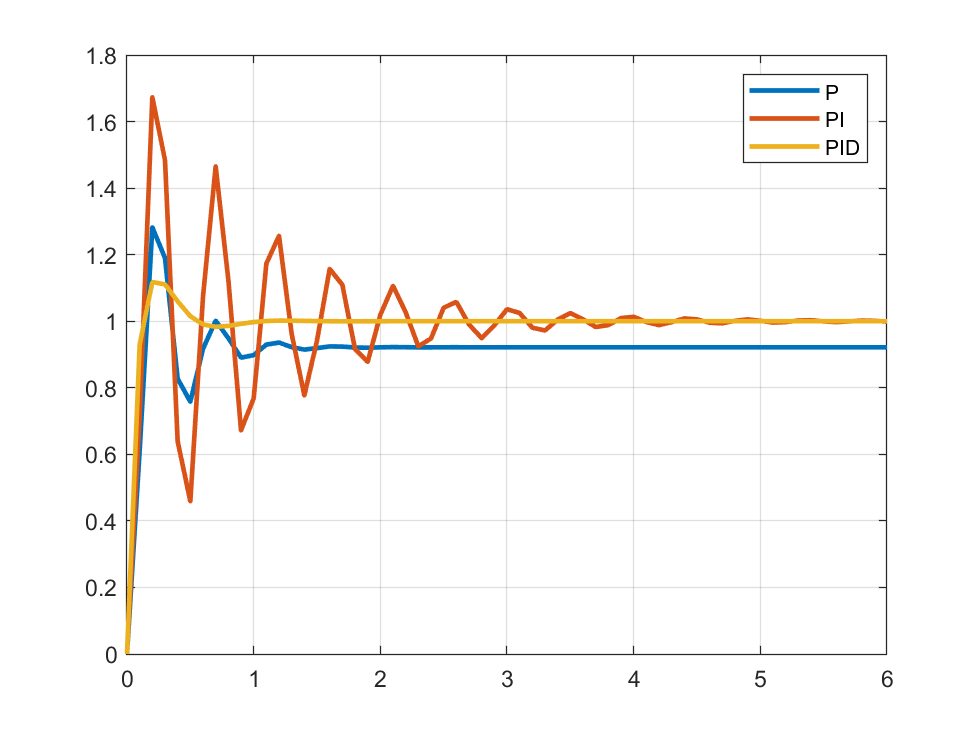

t = 0:0.1:6;
for i = 1:length(Kp)
    %% PID TF
    D = tf(Kp(i),1) + tf(Ki(i), [1 0]) + tf([Kd(i) 0],1);
    cltf = feedback(D*G,1);
    y(:,i) = step(cltf,t);
end

plot(t,y,'LineWidth',2);
legend('P','PI','PID');
grid on;